# Power-Split Drive Unit Model

Copyright 2021 The Mathworks, Inc.

## Open the Model

mdl = "PowerSplitDriveUnitBasic_test_harness";
if not(bdIsLoaded(mdl)), open_system(mdl); end

PowerSplitDriveUnitBasic_setup

## Load Inputs to Workspace

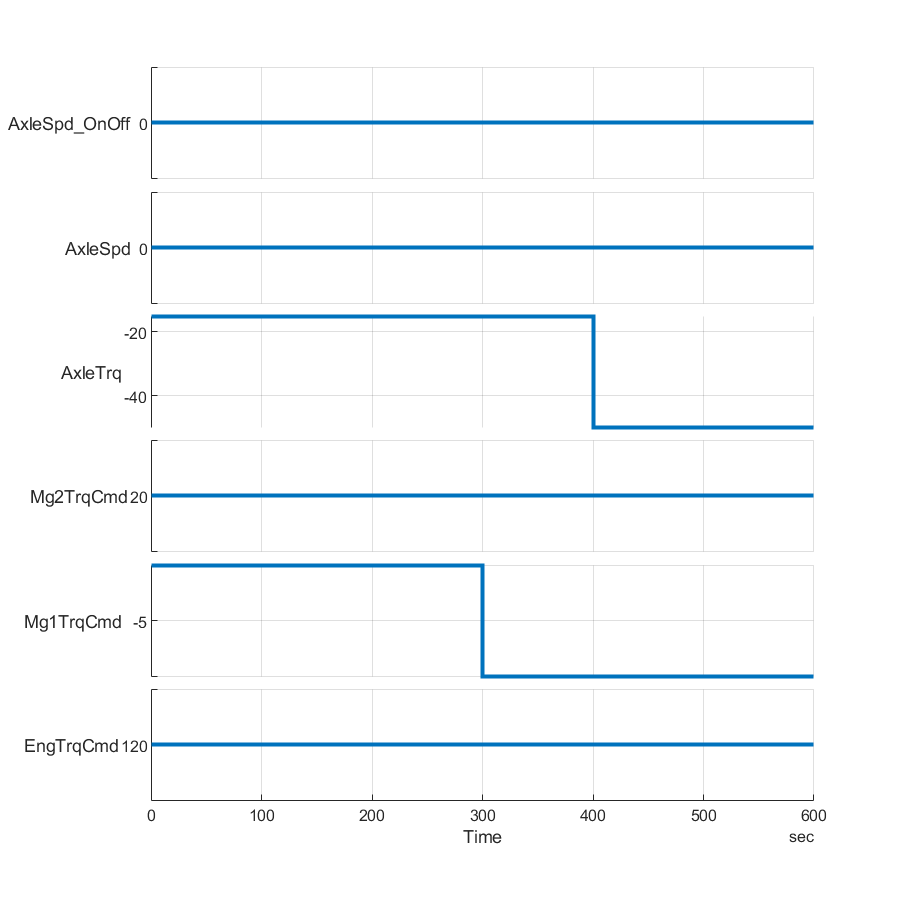

fig = figure;
[inputSignals_PSDU, inputBus_PSDU, t_end] = ...
  PowerSplitDriveUnitBasic_inputs( ...
    "PlotParent",fig, "InputPattern","power_split_drive" );

## Run Simulation

% Override initial conditions
initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

% Override parameters

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

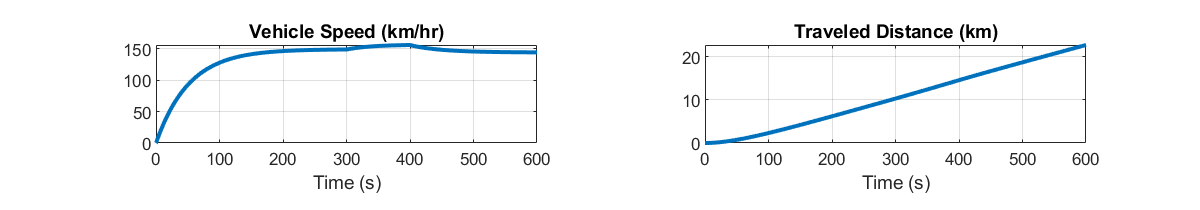

fig = figure;
fig.Position(3:4) = [800 200];
PowerSplitDriveUnitBasic_plot_vehicle("Dataset",out.logsout, "PlotParent",fig);

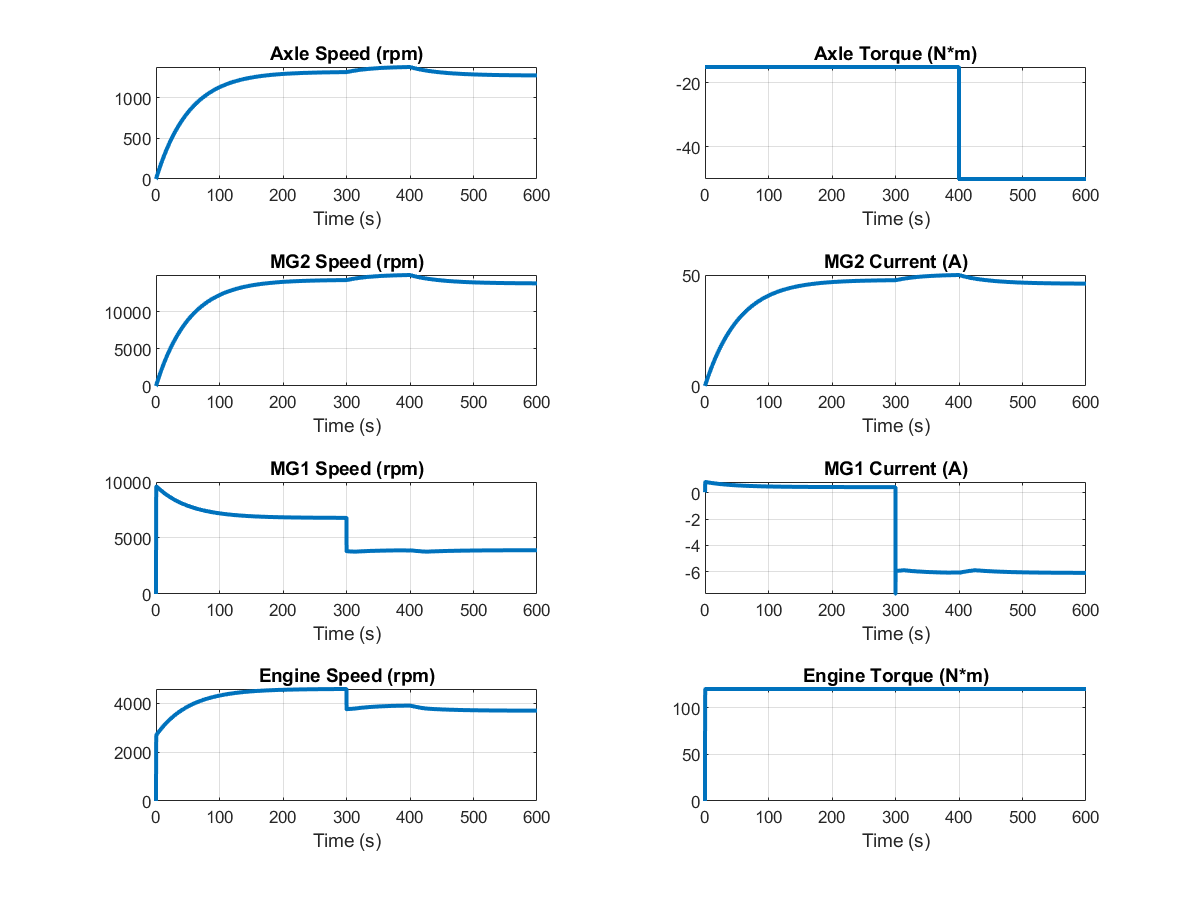

fig = figure;
fig.Position(3:4) = [800 600];
PowerSplitDriveUnitBasic_plot_psdu("Dataset",out.logsout, "PlotParent",fig);

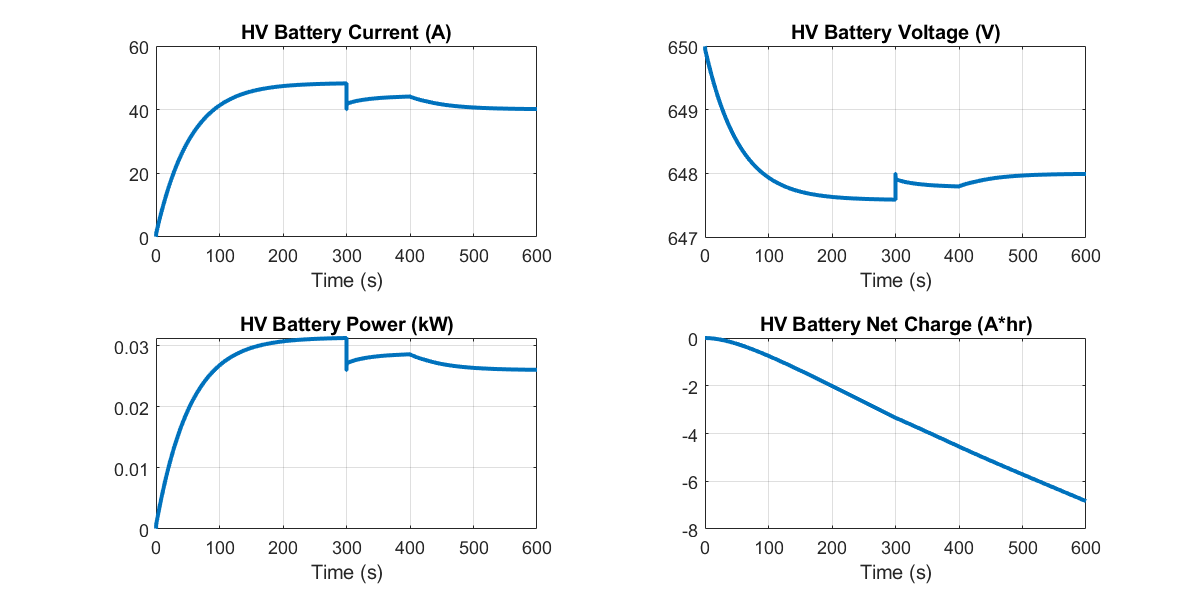

fig = figure;
fig.Position(3:4) = [800 400];
PowerSplitDriveUnitBasic_plot_hvbattery("Dataset",out.logsout, "PlotParent",fig);

## Analyze Model Behavior using Solver Profiler

Links to the documentation:

- [About Solver Profiler](https://www.mathworks.com/help/simulink/ug/examine-solver-behavior-using-solver-profiler.html)

- [Sover Profiler command](https://www.mathworks.com/help/simulink/slref/solverprofiler.profilemodel.html)

t_prof_start = 0;
t_prof_end = t_end;
assert( t_end >= t_prof_end )

res = solverprofiler.profileModel(mdl, ...
    'SaveStates', 'on', ...
    'SaveSimscapeStates', 'On', ...
    'SaveJacobian', 'Off', ...
    'StartTime', t_prof_start, ...  % When to start the profiler. (Not simulation start time)
    'StopTime', t_prof_end, ... % When to stop the profiler AND simulation.

    'BufferSize', 200000, ...

ans = 1.0186

    'TimeOut', 5, ...

ans = 'auto(ode23t)'

    'OpenSP', 'Off', ...  % Open Solver Profile window after simulation ends

ans = 1.0000e-03

    'DataFullFile', fullfile(pwd, 'ssc_profiling_result.mat'));

ans = 16

res.summary.profileTime
res.summary.solver
res.summary.absTol
res.summary.zcNumber

[Open](matlab:solverprofiler.exploreResult(res)) Solver Profiler dialog window with the result (res) being loaded.